# Natural Resources Management

# Final Project

addpath("utils\")

## Lake description

We have been given the dataset regarding the dam **Gabcikovo**, along Danube river. It is situated at the border between Slovakia and Hungary, in the slovakian territory, near its capital Bratislava.

The objectives considered in this project are: 

- To avoid big flood damages

- To improve the river navigability 

- Electrical energy production

The most relevant project dimensions are:

- The area of the Čunovo reservoir is 40 km², exclusively on the Slovakian side.

- The power station total capacity is 720 MW at operational discharge of 4000 m3/s. Water level differences are 24 and 12.88 m.

- The original river bed has a discharge of between 250 and 600 m3/s.

- Two navigation locks were built. A bypass canal will handle floods.

## Part 0. Data pre-processing

file = readmatrix("data\08Gabcikovo.csv");
data_precipitation = file(:,4); % [mm/d]
data_streamflow = file(:,5); % [m3/s]
data_temperature = file(:,6); % °C

### Dataset partition 

We use the 70% of the dataset the training the models and we the remaining 30% for validation.

It means that the data available corresponds to 27 years from 1990 to 2016, then we use the first 18 years up to 2008 to create a forecast model for the streamflow from 2009 to 2016.

T = 365;
tr_length = 0.70;
years_total = length(file) / T

years_total = 27

years_tr = floor(years_total*tr_length)

years_tr = 18

% Training dataset
x_tr = data_streamflow(1:T*years_tr);
u_tr = [data_precipitation(1:T*years_tr) data_temperature(1:T*years_tr)];
% Validation dataset
x_val = data_streamflow(T*years_tr+1:end);
u_val = [data_precipitation(T*years_tr+1:end) data_temperature(T*years_tr+1:end)];

### Cyclostationary  analysis

The cyclostationary analysis for the streamflow was useful to calculate the moving average and moving variance in a 5 days window for each day of the year in the training dataset. From the graph we can observe the number of events on each day in the various year (blue points), the average calculated (orange points)  and the variance (red points). This give us a perspective about the average behaviour of the streamflow in the period between 1990 and 2008, as an idea about the expected average behaviour for the incoming years.

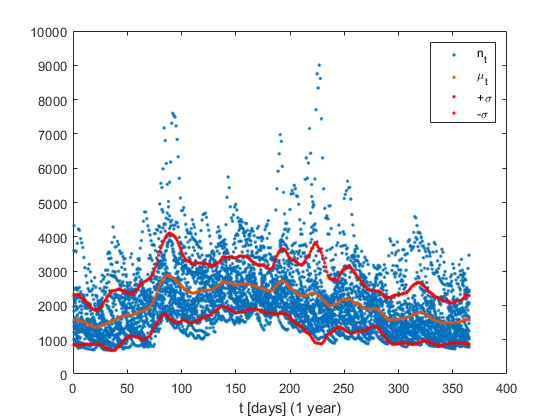

f = 5; 
N_tr = length(x_tr);
tt = repmat([1:T]', N_tr/T, 1);
% Moving Average
[mi, m] = moving_average(x_tr, T, f);
% Moving variance
[ma_var2, s2] = moving_average((x_tr - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);
figure;
plot(tt, [x_tr, m], '.');
xlabel('t [days] (1 year)');
hold on;
% plot([1 : T], mi, 'g', 'LineWidth',.5);
plot(tt, m + s, '.r');
plot(tt, m - s, '.r');
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

% legend('n_t', '\mu_t', '\mu_{cyclo}', '+\sigma', '-\sigma');

### Autocorrelations

To model the streamflow as a time series using an ARIMA model we need to analize the autocorrelation of the variable we want to predict in order to understand how usefull is the past and current data to estimate the future one. Following the Box-Jenkins method to find the best time-series model for an ARIMA process, we need to determine if the time series present some stationarity and seasonality first. 

- Stationarity: a stochastic process whose unconditional joint probability distribution does not change when shifted in time. Consequently, parameters such as mean and variance also do not change over time. 

- Seasonality: is the presence of variations that occur at specific regular time intervals

#### Streamflow

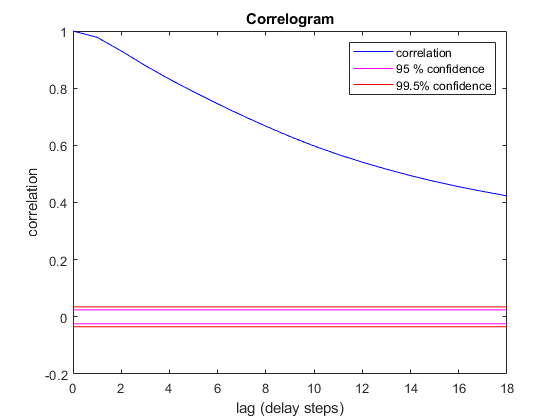

figure; correlogram(x_tr, x_tr, years_tr)

### Correlations

#### Streamflow - Precipitations

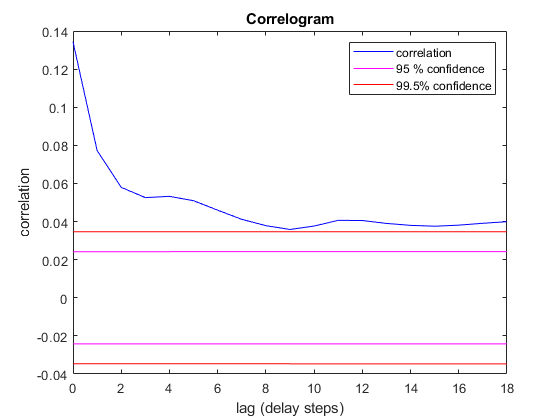

figure; correlogram(x_tr, u_tr(:,1), years_tr)

#### Streamflow - Temperature

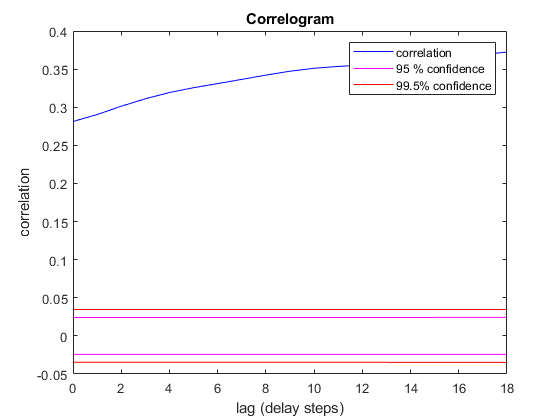

figure; correlogram(x_tr, u_tr(:,2), years_tr)

### Data normalization

The normalization performed gets rid of the seasonability that the data could present, specially in the streamflow - precipitation that has some oscillatory behaviour

f = 5; 
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm(:,1), mean_u(:,1), sigma_u(:,1)] = deseasonalize(u_tr(:,1), T, f);
[u_norm(:,2), mean_u(:,2), sigma_u(:,2)] = deseasonalize(u_tr(:,2), T, f);

[x_norm_val, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_norm_val(:,1), mean_u_val(:,1), sigma_u_val(:,1)] = deseasonalize(u_val(:,1), T, f);
[u_norm_val(:,2), mean_u_val(:,2), sigma_u_val(:,2)] = deseasonalize(u_val(:,2), T, f);

### Autocorrelation

From the autocorrelation analysis we can notice that there's a strong relation among the historical stream flow, almost 40% even 18 years later.

#### Streamflow

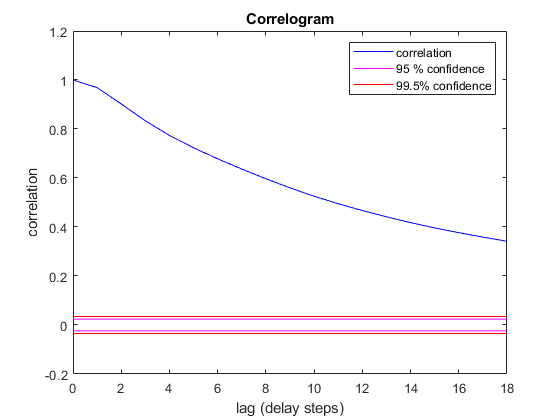

figure; correlogram(x_norm, x_norm, years_tr)

### Correlations

From the correlation analysis we conclude that even if the precipitation and temperature are affecting the current state of the streamflow, there's no accumulative behaviour so the past values of them are not affecting the current streamflow. We decide to use this information as an input for our models to improve the prediction performance.

#### Streamflow - Precipitations

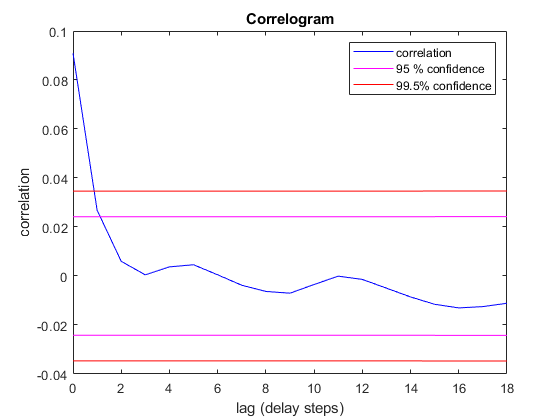

figure; correlogram(x_norm, u_norm(:,1), years_tr)

#### Streamflow - Temperature

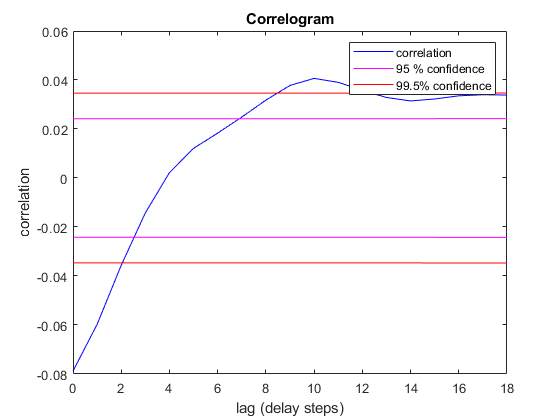

figure; correlogram(x_norm, u_norm(:,2), years_tr)

## Part 1. 1-day ahead forecast model

As a performance index we selected the R2 indicator, because it provides a measure of how well observed outcomes are replicated by the model, based on the proportion of total variation of outcomes  explained by the model.


$$R^2 =1-\frac{\sigma_{\textrm{XY}}^2 }{\sigma_X^2 \sigma_Y^2 }$$


Where:

$\sigma_{\textrm{XY}}^2$ is the covariance of the estimation

$\sigma_X^2 \sigma_Y^2$ is the variance of the data

### Linear models

#### AR (n)

Taking into account that the most meaningfull information for forecasting is in the historical data of the streamflow, we wanted to compare iteratively different models, starting from AR(1) up to AR(15) and in this way we validate the hipothesys that as much past data we use, more accurate will be our model. And this is confirmed in the $R^2$ graph comparing the 15 models.

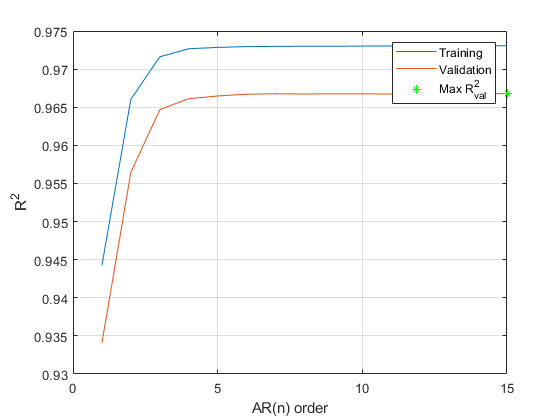

ar_iteation = 15;
r2_ar = nan(ar_iteation,1);
r2_ar_val = nan(ar_iteation,1);
r2_ar_val_max = 0;
ar_opt_idx = 0;
for i=1:ar_iteation
    [theta_ar_i, x_norm_ar] = trainAR(x_norm, i);
    x_norm_ar_val = estimateAR(x_norm_val, theta_ar_i, i);
    
%     Training
    r2_ar(i) = getR2Performance( ...
            x_tr, ...
            x_norm_ar, ...
            mean_x, ...
            sigma_x ...
        );
%     Validation
    r2_ar_val(i) = getR2Performance( ...
            x_val, ...
            x_norm_ar_val, ...
            mean_x_val, ...
            sigma_x_val ...
        );
    
    if r2_ar_val_max < r2_ar_val(i)
        theta_ar = theta_ar_i;
        ar_opt_idx = i;
        r2_ar_val_max = r2_ar_val(i);
    end
    
end
clear i
figure;
plot([r2_ar, r2_ar_val])
hold on 
plot (ar_opt_idx, r2_ar_val_max, '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('AR(n) order');ylabel('R^2');
grid on

#### Proper ARX (1,1)

For the sake of simplicity we decided to use just the previous value for forecast, we already know that as much past data we use, we can improve the model and we just need the current value of the inputs to set the forecast, then we consider that an AR(1,1) is enough to compare the results

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(1:end-1,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx = 0.9653

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_val = 0.9594

#### Improper ARX (1,1)

Notice that the improper model has a slightly worse performance than the proper one.**TODO: explain why**

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(2:end,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx_imp = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx_imp = 0.9490

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_imp_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_imp_val = 0.9504

### Nonlinear models

#### Proper ANN

The model used is an ANN with 3 neurons, iterated 10 times to find the best model possible. We decided to use as less neurons as possible to keep the model simple as well. Notice that even after 10 iterations the validation performance doesn't change too much, then we can state that with this model is not sensitive to training.

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(1:end-1,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_prop = zeros(N_runs, 1);
r2_ann_prop_val = zeros(N_runs, 1);
ann_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_prop_i = feedforwardnet(3);
    ann_prop_i = train(ann_prop_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_prop_i(x_ann);
    y_ann_prop = [x_norm(1); y'];
    r2_ann_prop(i) = getR2Performance(x_tr, y_ann_prop, mean_x, sigma_x);
    
    % Validation
    y = ann_prop_i(x_ann_val);
    y_ann_prop_val = [x_norm_val(1); y'];
    r2_ann_prop_val(i) = getR2Performance(x_val, y_ann_prop_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_prop_val(i) >= max(r2_ann_prop_val)
        ann_prop = ann_prop_i; % Optimal ANN wrt validation dataset
        ann_opt_idx = i;
    end
    
end


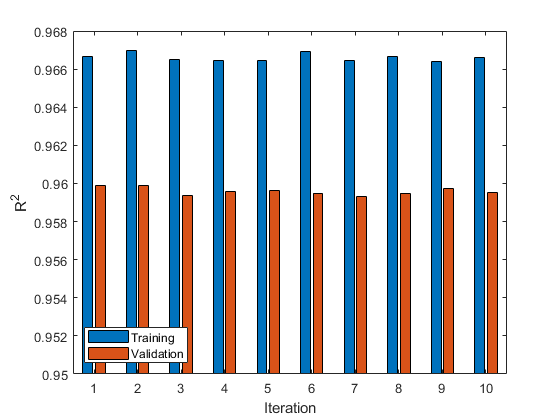

figure; 
h = bar([r2_ann_prop, r2_ann_prop_val], 'BaseValue',0.95);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend('location','southwest')

#### Improper ANN

The improper model has a slightly worse performance than the proper one.

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(2:end,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_improp = zeros(N_runs, 1);
r2_ann_improp_val = zeros(N_runs, 1);
ann_improp_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_improp_i = feedforwardnet(3);
    ann_improp_i = train(ann_improp_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_improp_i(x_ann);
    y_ann_improp = [x_norm(1); y'];
    r2_ann_improp(i) = getR2Performance(x_tr, y_ann_improp, mean_x, sigma_x);
    
    % Validation
    y = ann_improp_i(x_ann_val);
    y_ann_improp_val = [x_norm_val(1); y'];
    r2_ann_improp_val(i) = getR2Performance(x_val, y_ann_improp_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_improp_val(i) >= max(r2_ann_improp_val)
        ann_improp = ann_improp_i; % Optimal ANN wrt validation dataset
        ann_improp_opt_idx = i;
    end
    
end


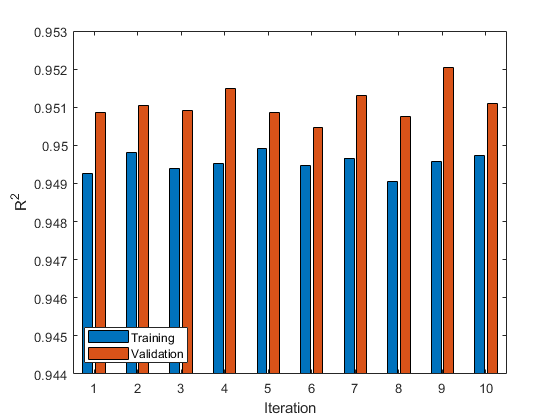

figure; 
h = bar([r2_ann_improp, r2_ann_improp_val],'BaseValue',0.944);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend('location','southwest')

#### CART

The leaf size is iterated between 1 and 40 to find the optimal leaf size. Notice that with this iterative method the leaf size with the best performance is 34 and the one found by the auto-tool is 26 and this is due to the fact of continues evaluation we did assuming that the optimal could be found in the interval we set, but the difference between them is just 0.001%, then is reliable to use the auto-tool instead the compute intensive continuous iteration.

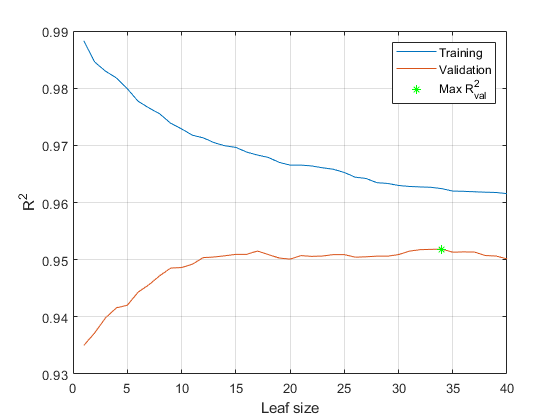

x_cart = [x_norm(1:end-1), u_norm(1:end-1,:)];
y_cart = x_norm(2:end);

x_cart_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
y_cart_val = x_norm_val(2:end);
    
max_leaf_size = 40;
r2_cart = zeros(max_leaf_size,1);
r2_cart_val = zeros(max_leaf_size,1);
leafsize_opt = 0;

for i = 1:max_leaf_size
    T_i = fitrtree(x_cart, y_cart,'MinLeafSize',i);
    % view(T, 'mode', 'graph');
    y = predict(T_i, x_cart);
    y_cart_predict = [x_norm(1); y];
    r2_cart(i) = getR2Performance(x_tr, y_cart_predict, mean_x, sigma_x);
    
%     Validation
    y = predict(T_i, x_cart_val);
    y_cart_predict_val = [x_norm_val(1); y];
    r2_cart_val(i) = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val);
    
    if r2_cart_val(i) >= max(r2_cart_val)
        T_opt = T_i; % Optimal ANN wrt validation dataset
        leafsize_opt = i;
    end 
end

figure;
plot([r2_cart, r2_cart_val])
hold on
plot (leafsize_opt, r2_cart_val(leafsize_opt), '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('Leaf size');ylabel('R^2');
grid on

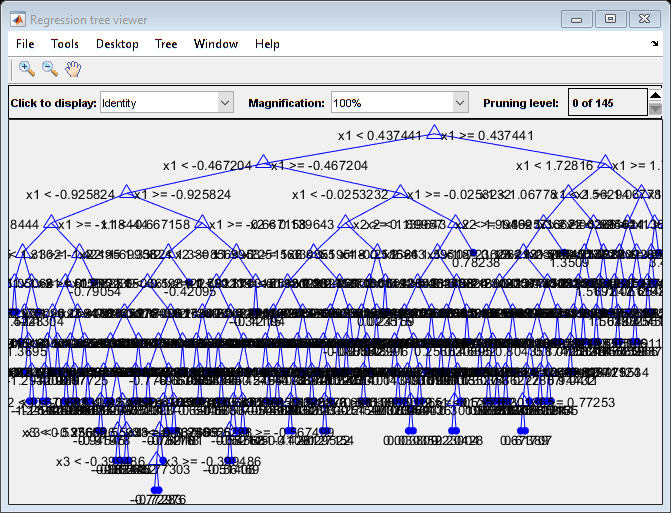

view(T_opt,'mode','graph')

T_opt.NumNodes

ans = 301

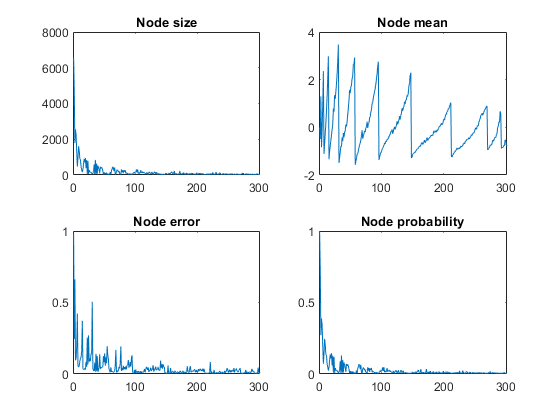

figure
subplot(2,2,1); plot( T_opt.NodeSize ); title('Node size'); % number of samples per node
subplot(2,2,2); plot( T_opt.NodeMean ); title('Node mean'); % mean samples in each node
subplot(2,2,3); plot( T_opt.NodeError ); title('Node error'); % node error
subplot(2,2,4); plot( T_opt.NodeProbability); title('Node probability')

Then is compared with the algorithm that finds the optimal solution by a smart search of params

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.045409 |      1.5391 |    0.045409 |    0.045409 |           23 |


|    2 | Accept |    0.079015 |     0.16644 |    0.045409 |    0.049154 |          268 |


|    3 | Accept |    0.059629 |     0.50469 |    0.045409 |    0.048201 |            1 |


|    4 | Accept |     0.68684 |    0.079029 |    0.045409 |    0.077067 |         2889 |


|    5 | Accept |     0.22952 |     0.18619 |    0.045409 |     0.22008 |         1311 |


|    6 | Accept |    0.057785 |    0.085029 |    0.045409 |     0.11319 |          127 |


|    7 | Accept |    0.057785 |    0.066406 |    0.045409 |    0.045423 |          127 |


|    8 | Accept |    0.062377 |    0.064533 |    0.045409 |    0.045418 |          170 |


|    9 | Accept |    0.053941 |     0.33125 |    0.045409 |    0.045416 |            4 |


|   10 | Accept |    0.052323 |     0.08883 |    0.045409 |    0.045412 |           73 |


|   11 | Accept |    0.057957 |     0.54198 |    0.045409 |    0.045409 |            2 |


|   12 | Accept |    0.048901 |     0.14845 |    0.045409 |    0.045408 |            8 |


|   13 | Accept |    0.047859 |    0.071076 |    0.045409 |    0.045401 |           48 |


|   14 | Accept |    0.046715 |     0.11085 |    0.045409 |     0.04539 |           12 |


|   15 | Accept |    0.046584 |    0.077545 |    0.045409 |    0.045413 |           38 |


|   16 | Accept |    0.046004 |     0.12336 |    0.045409 |    0.045398 |           14 |


|   17 | Accept |    0.046142 |      0.1029 |    0.045409 |    0.045404 |           34 |


|   18 | Accept |    0.045574 |     0.16441 |    0.045409 |    0.045953 |           15 |


|   19 | Accept |    0.045901 |    0.094324 |    0.045409 |    0.045827 |           16 |


|   20 | Accept |    0.045514 |    0.097713 |    0.045409 |    0.045662 |           17 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Best   |     0.04518 |    0.092892 |     0.04518 |     0.04566 |           25 |


|   22 | Accept |    0.045708 |    0.088795 |     0.04518 |    0.045409 |           21 |


|   23 | Accept |    0.045271 |     0.11818 |     0.04518 |    0.045357 |           27 |


|   24 | Accept |    0.045271 |     0.09127 |     0.04518 |    0.045328 |           27 |


|   25 | Accept |     0.11571 |    0.051754 |     0.04518 |    0.045326 |          611 |


|   26 | Accept |    0.092589 |    0.084624 |     0.04518 |    0.045325 |          405 |


|   27 | Accept |    0.050352 |     0.21984 |     0.04518 |    0.045326 |            6 |


|   28 | Accept |    0.053474 |    0.069586 |     0.04518 |    0.045327 |           95 |


|   29 | Accept |    0.056669 |     0.35049 |     0.04518 |    0.045327 |            3 |


|   30 | Accept |     0.20676 |    0.053141 |     0.04518 |    0.045243 |          886 |


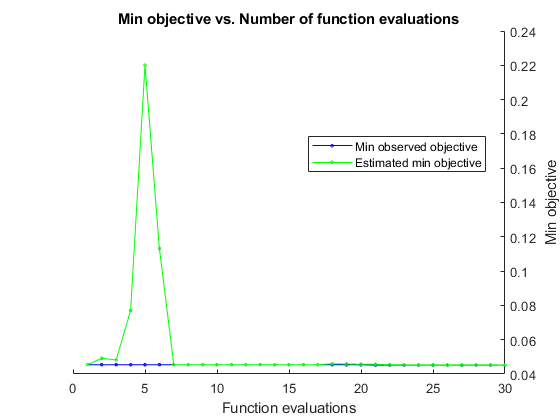

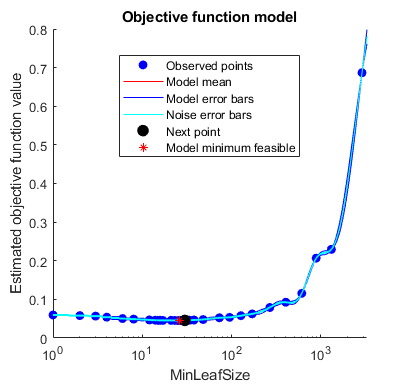


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 40.8614 seconds.
Total objective function evaluation time: 5.8646

Best observed feasible point:
    MinLeafSize
    ___________

        25     

Observed objective function value = 0.04518
Estimated objective function value = 0.045243
Function evaluation time = 0.092892

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        25     

Estimated objective function value = 0.045243
Estimated function evaluation time = 0.12336



T_opt_auto = fitrtree(x_cart, y_cart,'OptimizeHyperparameters','auto');

y = predict(T_opt_auto, x_cart_val);
y_cart_predict_val = [x_norm_val(1); y];
r2_cart_auto_val = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val)

r2_cart_auto_val = 0.9509

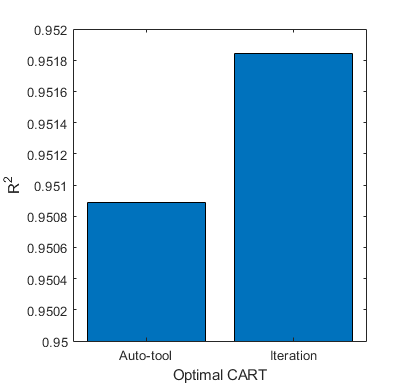

c = categorical({'Iteration','Auto-tool'});
bar(c, [max(r2_cart_val); r2_cart_auto_val],'BaseValue',0.95)
xlabel('Optimal CART');ylabel('R^2');

### Models comparison

figure;
c = categorical({ ...
    'AR(1)', ...
    'AR(opt)', ...
    'ARX(1,1) Proper', ...
    'ARX(1,1) Improper', ...
    'ANN(3) Proper', ...
    'ANN(3) Improper', ...
    'CART', ...
    });

The result is that the model with the best performance (r2=0.9668) is the **AR(15)**, but simper models as the** ARX(1,1)** (r2=0.9594) and **proper ANN **(0.9599) give a good result as well. We already know that using more past data will improve the AutoRegresive part of the ARX and adding more neurons before overfitting will improve the ANN as universal approximator. But we consider that all this models are above a 95% on the validation dataset, then we can predict with an enough big accuracy the streamflow for the next day.

r2_index = [ ...
    r2_ar(1), r2_ar_val(1); ...
    r2_ar(ar_opt_idx), r2_ar_val(ar_opt_idx); ...
    r2_arx, r2_arx_val; ...
    r2_arx_imp, r2_arx_imp_val; ...
    r2_ann_prop(ann_opt_idx), r2_ann_prop_val(ann_opt_idx); ...
    r2_ann_improp(ann_improp_opt_idx), r2_ann_improp_val(ann_improp_opt_idx); ...
    r2_cart(leafsize_opt), r2_cart_val(leafsize_opt); ...
    ]

r2_index =     0.9443    0.9341
    0.9731    0.9668
    0.9653    0.9594
    0.9490    0.9504
    0.9667    0.9599
    0.9496    0.9520
    0.9624    0.9518


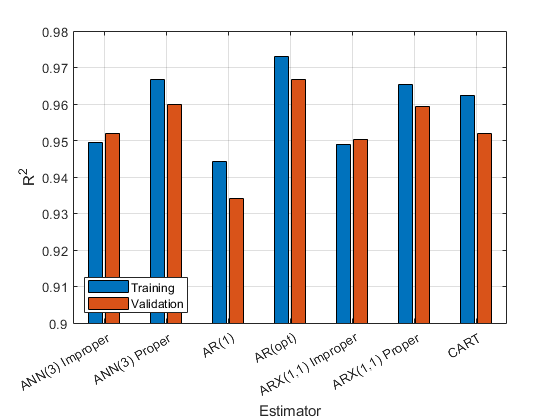

% latex(sym(r2_index))
h = bar(c,r2_index,'BaseValue',0.9);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend("Location","southwest")
grid on

## Part 2. Damming policies

**TODO: **Justify lake surface

### Dam sizing

% years_total = 27;
% lake_surface = 133257.80e6; % [m2]
lake_surface = 90e6; % [m2]
Q_month = dailyToMonthly(data_streamflow, years_total);
% https://www.hausamstrom.de/wp-content/uploads/2018/12/Folder_EnergieerlebnisJochenstein-eng.pdf

**TODO**: Justify target release

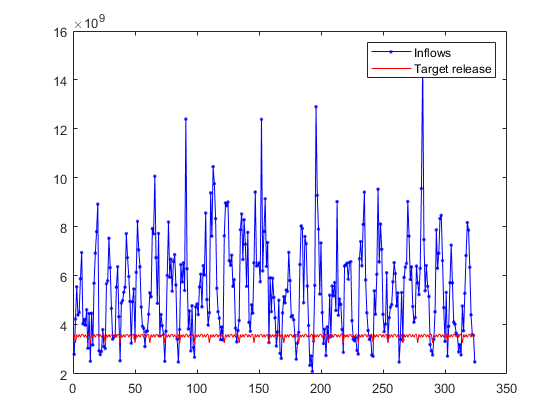

w = 1350; % [m3/s] Target release - Downstrem demand [% wrt...]
% w = 2350*.85; % [m3/s] Target release - Downstrem demand [% wrt...]
% w = prctile(Q_month,40);
% w = mean(w);
deltaT = 3600*24*[31 28 31 30 31 30 31 31 30 31 30 31]';
Q = Q_month(:).*repmat(deltaT,years_total,1) ; % [m3/month]
W = w*ones(size(Q)).*repmat(deltaT,years_total,1) ; % [m3/month]

figure;
plot(Q, '.-b'); hold on
plot(W, 'r');
legend('Inflows', 'Target release')

#### Rippl criteria

**TODO: **Choose one criteria, justify the decision and explain the value and how is used to calculate the dam heigth

[rippl] = abs(getRipple(W,Q))

rippl = 8.1449e+08

#### Sequent Peak Analysis criteria

[spa, K] = getSPA(W,Q)

spa = 3.5399e+09

K = 	1.0e+09 *

         0
    0.8145
         0
         0
         0
         0
         0
         0
         0
         0


h_max = max(rippl, spa)/lake_surface

h_max = 39.3317

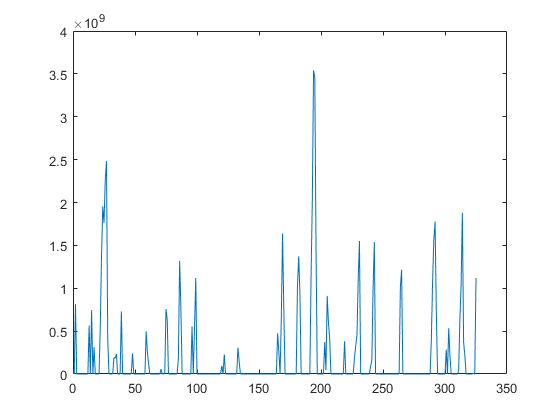

figure;
plot(K)

### Define Standard Operating policy

One alternative is to use the value up to the mean + one standard deviation. 

**TODO: **Justify why we choose the max release like this

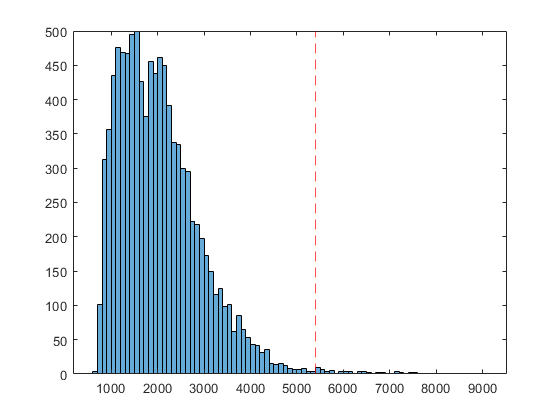

% max_nat_release_est = 3000;
% max_nat_release_est = round(mean(data_streamflow) + std(data_streamflow), 3, 'significant'); % [m3/s]
max_nat_release_est = max(data_streamflow)*.60;
figure;
histogram(data_streamflow)
hold on;
xline(max_nat_release_est,'--r');

### Trajectories Alternative-0 vs SOP

### Alternative 1: Balanced

**TODO: **Explain why it is supposed to be balanced

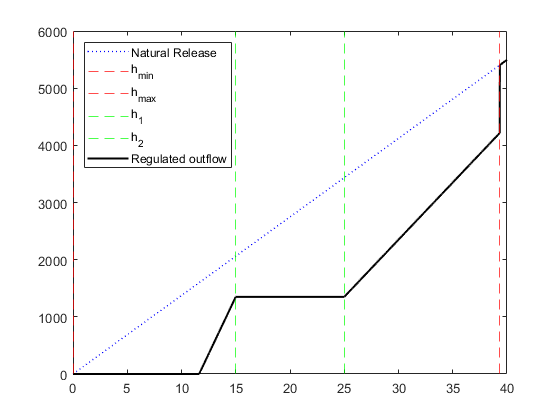

h_init = 30;   % Initial state of reservoir
h_bar = h_max; % Flooding thereshold

param.reg.h1 = 15;
param.reg.h2 = 25;
param.reg.m1 = 400;
param.reg.m2 = 200;

[r_reg1, s_reg1, h_reg1] = simRegLakeSimplified(h_init, data_streamflow, param);

get_regulated_policy(w, lake_surface, max_nat_release_est, h_max,param.reg.m1, param.reg.m2, param.reg.h1, param.reg.h2);

### Alternative 2: Improves reliability

**TODO: **Explain why it is supposed improve reliability

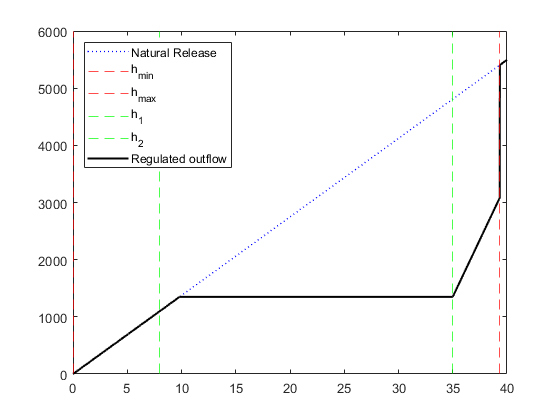

param.reg.h1 = 8;
param.reg.h2 = 35;
param.reg.m1 = 100;
param.reg.m2 = 400;

[r_reg2, s_reg2, h_reg2] = simRegLakeSimplified(h_init, data_streamflow, param);
get_regulated_policy(w, lake_surface, max_nat_release_est, h_max,param.reg.m1, param.reg.m2, param.reg.h1, param.reg.h2);

[r_nat, s_nat, h_nat] = simNatLakeSimplified(h_init, data_streamflow, param);


**TODO: **Some comments about the simulated policies with respect to the natural release

- Release

- Surface

- Heigth

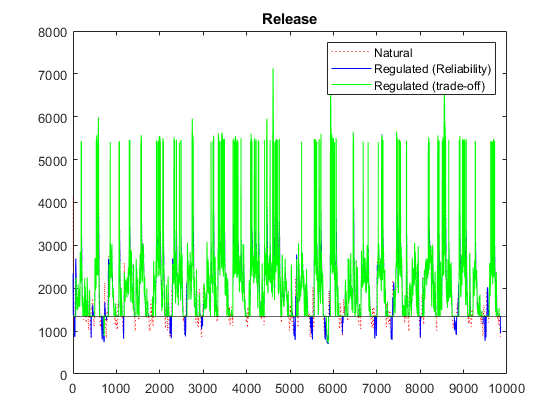

labels = {'Natural','Regulated (Reliability)','Regulated (trade-off)'};

figure; 
plot (r_nat, ':r');
hold on; 
plot(r_reg1,'b'); 
plot(r_reg2,'g'); 
yline(w);
title('Release');legend(labels);

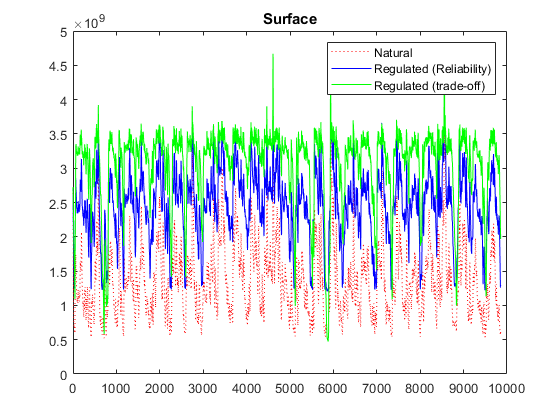

figure;
plot (s_nat, ':r');
hold on; 
plot(s_reg1, 'b');
plot(s_reg2, 'g');
title('Surface');legend(labels);

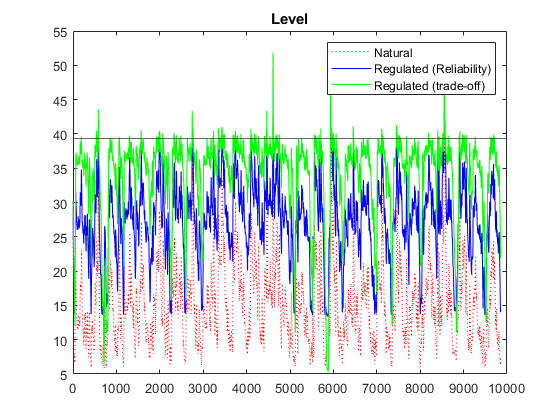

figure; 
plot (h_nat, ':r');
hold on;
plot(h_reg1, 'b');
plot(h_reg2, 'g');
yline(h_max);
title('Level');legend(labels);

### Indicators

#### Reliability

Water availability

**TODO:** Add the definition of this indicator

I_rel_sop1 = getReliability(r_reg1, w)

I_rel_sop1 = 0.9458

I_rel_sop2 = getReliability(r_reg2, w)

I_rel_sop2 = 0.9929

I_rel_nat = getReliability(r_nat, w)

I_rel_nat = 0.8026

#### Flooding 1

Number of days in the year to expect to have flooding

**TODO:** Add the definition of this indicator

I_f1_reg1 = getFlooding1(h_reg1,h_bar,years_total)

I_f1_reg1 = 3.7407

I_f1_reg2 = getFlooding1(h_reg2,h_bar,years_total)

I_f1_reg2 = 15.9630

I_fl_nat = getFlooding1(h_nat,h_bar,years_total)

I_fl_nat = 1.0370

**TODO: **Some comments about the pareto frontier or the values in between the max and the min

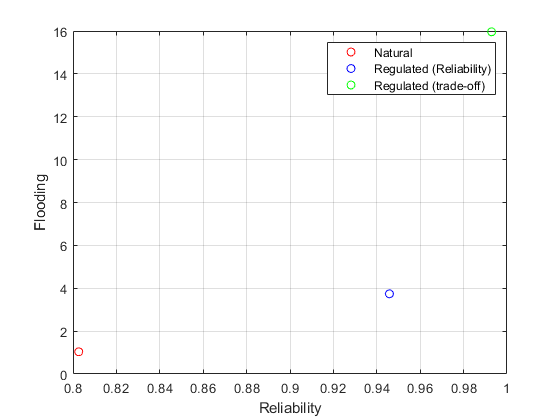

figure; plot(I_rel_nat, I_fl_nat, 'ro')
hold on; plot(I_rel_sop1, I_f1_reg1, 'bo')
hold on; plot(I_rel_sop2, I_f1_reg2, 'go')
grid on;
xlabel('Reliability')
ylabel('Flooding')
legend(labels)

#### NOTE: Ignore this

#### *Resilience

getResilience(r_nat, w)

ans = 0.0463

getResilience(r_reg, w)

ans = 0.0393

### <Vulnerability (1)

Magnitude of a failure

getVulnerability1(r_nat, w)

ans = 225.2092

getVulnerability1(r_reg, w)

ans = 319.3075

### >Vulnerability (2)

Same as (1) from the point of view of the stakeholder, taking into account the risk aversion

n = 2; % Risk aversion factor
getVulnerability2(r_nat, w, n)

ans = 1.4388e+04

getVulnerability2(r_reg, w, n)

ans = 3.6851e+03

## Environment

% Define percentiles
LP_nat = prctile ( r_nat , 25)

LP_nat = 1.4479e+03

HP_nat = prctile ( r_nat , 75)

HP_nat = 2.4942e+03

LP_reg = prctile ( r_reg , 25)

LP_reg = 1350

HP_reg = prctile ( r_reg , 75)

HP_reg = 2.4925e+03

### Environment (1 - 2) Release

I_E1_nat = sum ( r_nat < LP_nat) / years_total

I_E1_nat = 91.2222

I_E2_nat = sum ( r_nat > HP_nat) / years_total

I_E2_nat = 91.2222

I_E1_reg = sum ( r_reg < LP_nat) / years_total

I_E1_reg = 127.4815

I_E2_reg = sum ( r_reg > HP_nat) / years_total

I_E2_reg = 91.1111

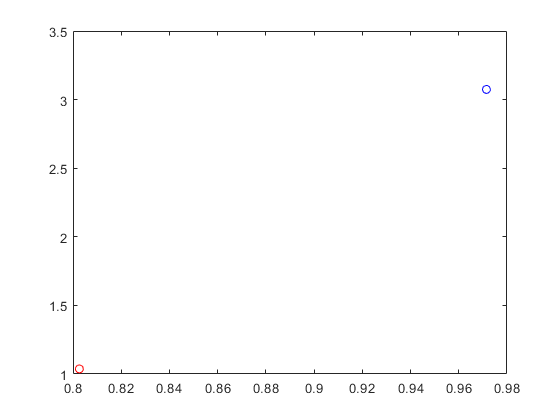

% J_nat = [I_rel_nat, I_fl_nat];
% J_reg = [I_rel_sop, I_f1_reg];
figure; plot(I_rel_nat, I_fl_nat, 'ro')
hold on; plot(I_rel_sop, I_f1_reg, 'bo')